function plotCSV1(csvFile)
% Genera gráficos de kcMax, SNR y resolución espacial a partir de un CSV
% csvFile: ruta del archivo CSV generado previamente con kcMax y SNR

    % Leer datos del CSV
    data = readtable(csvFile);

    % Extraer el número de iteraciones desde el nombre del archivo
    iter = zeros(height(data),1);
    for i = 1:height(data)
        fname = data.Filename{i};
        % Busca el número tras "iter"
        tokens = regexp(fname, 'iter(\d+)', 'tokens');
        if ~isempty(tokens)
            iter(i) = str2double(tokens{1}{1});
        else
            warning('No se encontró iteración en el nombre: %s', fname);
            iter(i) = NaN;
        end
    end

    % Extraer kcMax y SNR
    kcMax = data.kcMax;
    SNR = data.SNR;

    % Calcular resolución espacial (RE)
    PPS = 64; % nm
    RE = (2 * PPS) ./ kcMax;

    % === Gráfico 1: kcMax ===
    figure;
    plot(iter, kcMax, 'o-b','LineWidth',1.5,'MarkerFaceColor','b');
    xlabel('Número de iteraciones');
    ylabel('kcMax');
    title('Evolución de kcMax con el número de iteraciones');
    grid on;

    % === Gráfico 2: SNR ===
    figure;
    plot(iter, SNR, 's-r','LineWidth',1.5,'MarkerFaceColor','r');
    xlabel('Número de iteraciones');
    ylabel('SNR');
    title('Evolución de la SNR con el número de iteraciones');
    grid on;

    % === Gráfico 3: Resolución Espacial ===
    figure;
    plot(iter, RE, 'd-g','LineWidth',1.5,'MarkerFaceColor','g');
    xlabel('Número de iteraciones');
    ylabel('Resolución espacial (nm)');
    title('Resolución espacial estimada en función de las iteraciones');
    grid on;

    fprintf('Gráficos generados correctamente.\n');
end


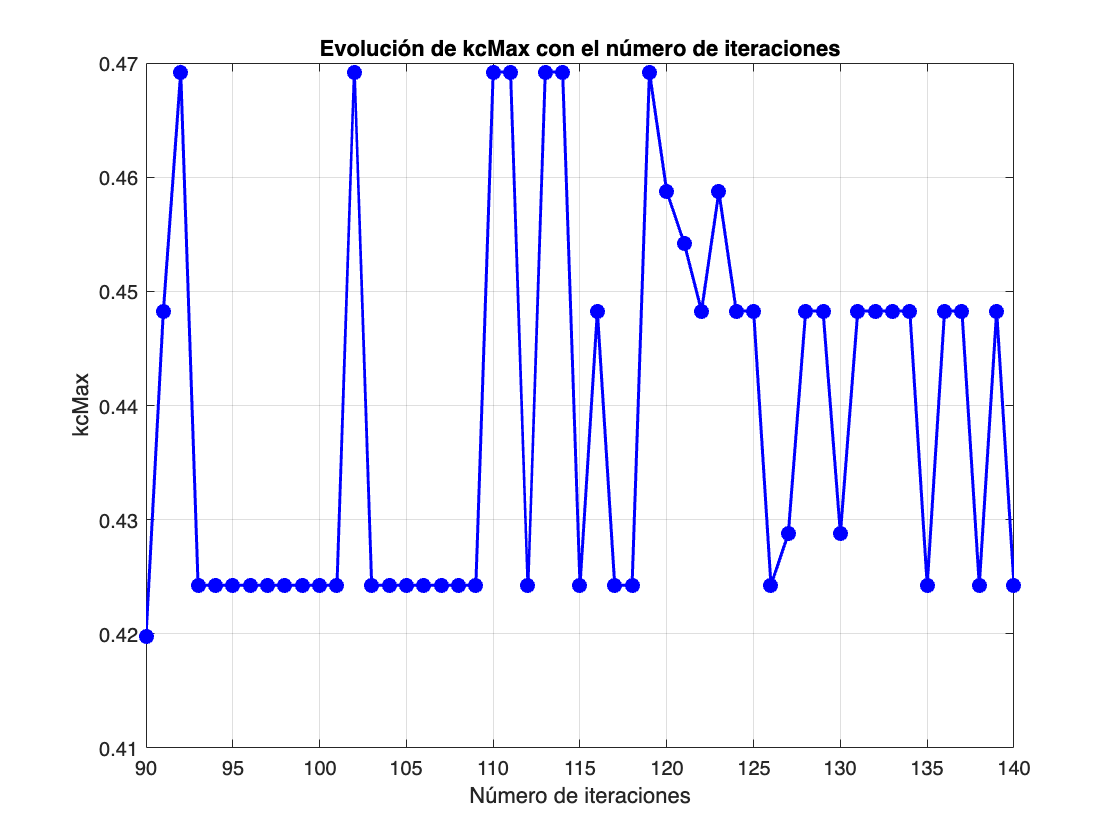

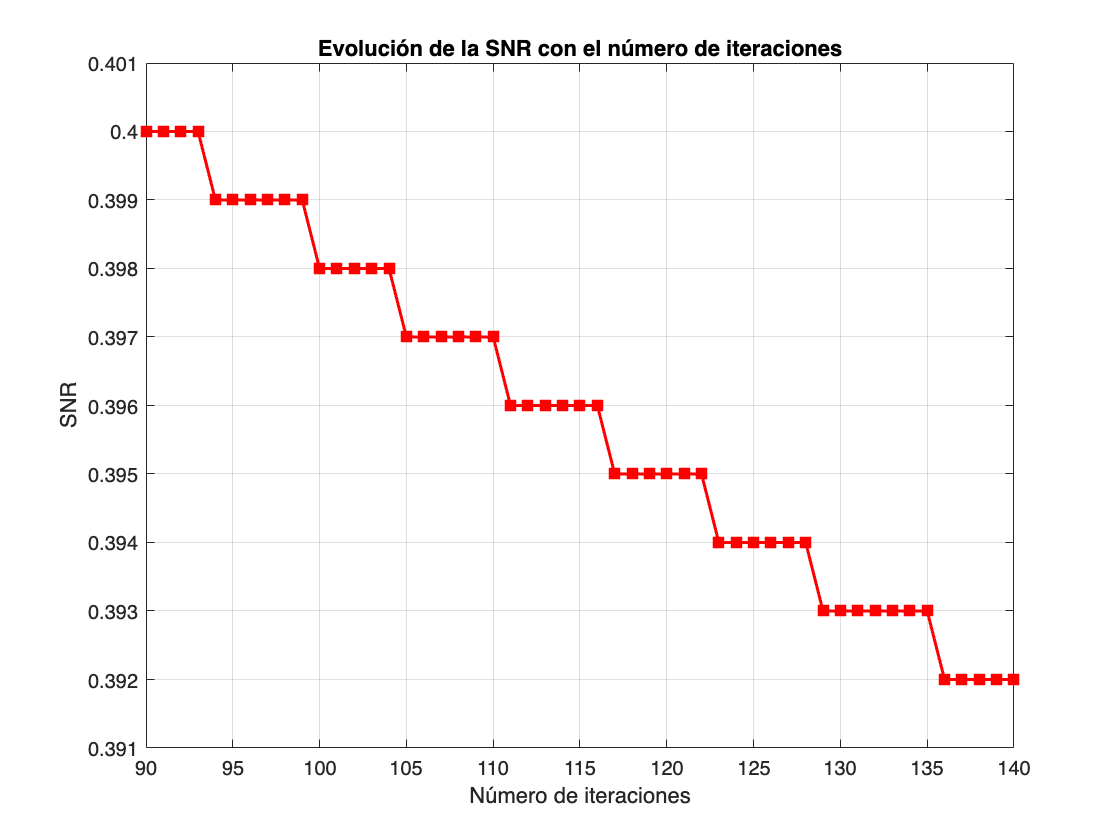

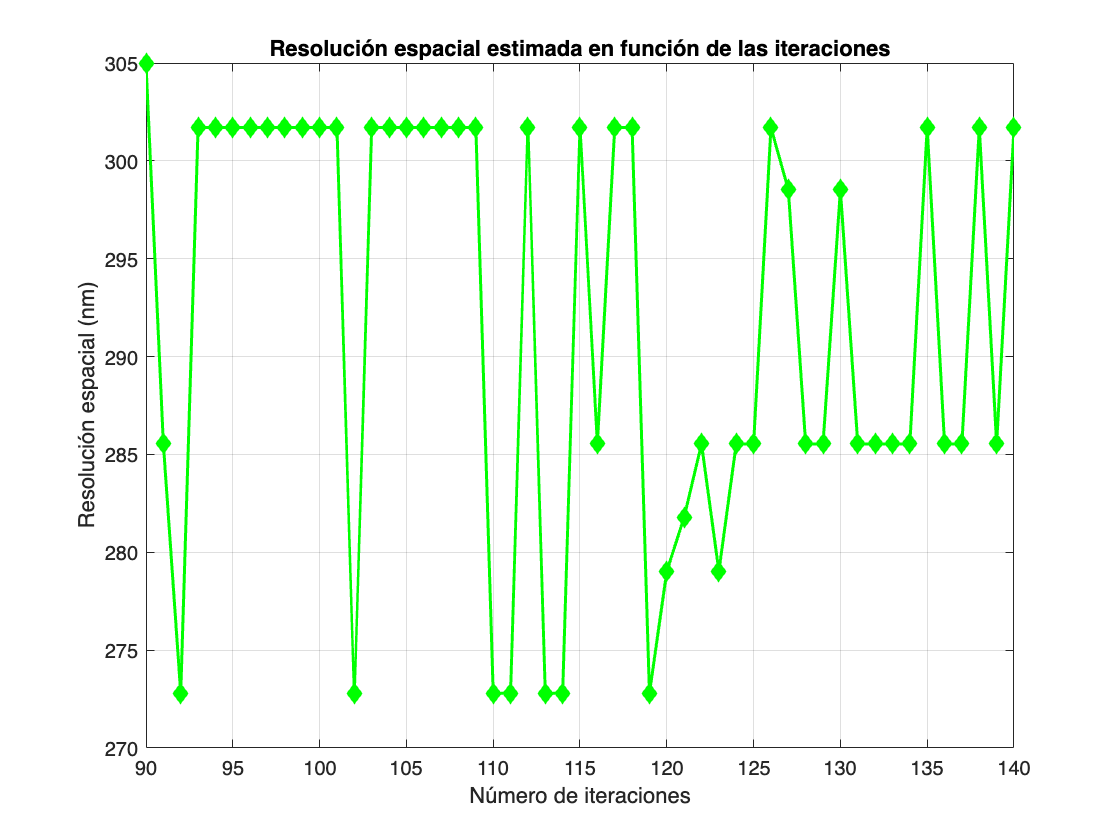

Gráficos generados correctamente.


plotCSV1('JULIA_Barrido_C1_ex/Resultados_kcMax_SNR.csv')